clear 
clc

V0 = 0.895;                     % input swing
C1 = 38.72E-12;                 % load cap
Fs = 10E6;                     % sample rate
wt = [101, 249, 499] / 1024;     
Fin = wt .* Fs;                 % input frequency (Hz)
Ron0 = 6.5*4;                     % On-Resistance (ohm)
L = [0.2, 0.4, 0.6,0.8, 1, 2, 3];
alpha = [-1.15, -0.15, 0.15, 0.3, 0.4, 0.6, 0.68];
VTH = 0.457;

% getHD_new(Ron, V0, C1, Fin(3), alpha(1))
%SD Exchange effect


Cb = 5;
C10 = 1;
C20 = 0.5;
C30 = 0;
Cp1 = 0;
Cp2 = 0.34;
Cp3 = 0.34;

Ctot = Cb + C10 + C20 + C30 + Cp1 + Cp2 + Cp3;
% Vgs0 = [Cb * 1.8 - (Cp1 + Cp2)*0.9 - Cp3 * 0.18] / Ctot  
Vgs1 = V0* (C10+Cp1)/Ctot;
mag2db(Vgs1)

ans = -18.0860

Vgs0 = [Cb * 1.8 - (C10+Cp1 + C20+1/3*Cp2 )*0.9 - (C30+1/3*Cp3 * 0.183)] / Ctot  

Vgs0 = 1.0484

% Vgs0 = 0.82
KV = Vgs1 / (Vgs0-VTH);
% Vgs0 = db2mag(0.293)
mag2db(Vgs0)

ans = 0.4102

% Vgs0 = db2mag(0.71)
Ron = 1/((Vgs0-VTH)*(280E-6 * 32 * 12 / 0.2))

Ron = 3.1455

% Ron = Ron0/4 * (1.8-VTH) / (Vgs0 - VTH)
% Ron = db2mag(7.5)
mag2db(Ron)

ans = 9.9537

getHD_new(Ron, V0, C1, Fin(3), alpha(1))

ans =  -111.5079 -113.5291



R2 = (KV^2 + KV^4)* Ron / 2

R2 = 0.0730


R1 = (Vgs1/(Vgs0-VTH)) * Ron;
mag2db(R1)

ans = -3.5694

mag2db(R2)

ans = -22.7356

mag2db(R2*C1*Fin(3)*pi*V0)

ans = -88.2414

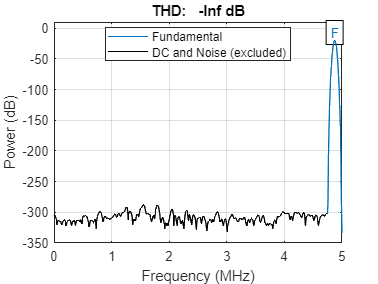

ans = -Inf

t = 0:1/Fs:1/Fs*1023;
omega = 2*pi*Fin(3);
Vgs = Vgs0 + Vgs1*sin(omega*t);
thd(Vgs, Fs)

ron_o = 1./((Vgs - VTH).*(280E-6 * 32 * 12/0.2));


ron = db2mag(6.11) + db2mag(-19.03)*sqrt(2)*sin(omega*t) - db2mag(-49.51)*sqrt(2)*sin(2*omega*t) +...
    db2mag(-86)*sqrt(2)*sin(3*omega*t)

ron =     2.0207    2.0341    1.9970    2.0604    1.9738    2.0856    1.9517    2.1088    1.9310    2.1295    1.9122    2.1470    1.8958    2.1610    1.8823    2.1711    1.8720    2.1771    1.8653    2.1790    1.8624    2.1769    1.8636    2.1709    1.8688    2.1613    1.8782    2.1484    1.8914    2.1325    1.9083    2.1142    1.9284    2.0938    1.9512    2.0719    1.9760    2.0489    2.0022    2.0253    2.0289    2.0016    2.0554    1.9782    2.0808    1.9558    2.1045    1.9348    2.1257    1.9156


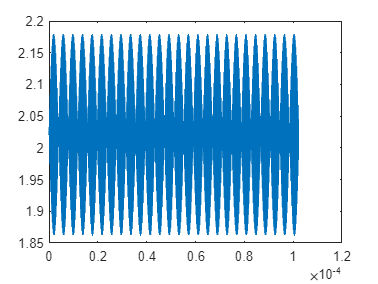

plot(t,ron)

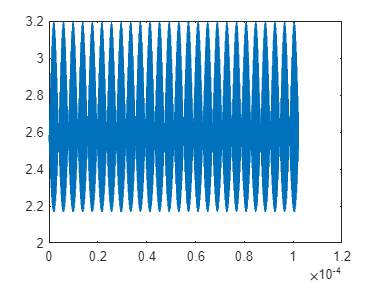

plot(t, ron_o)

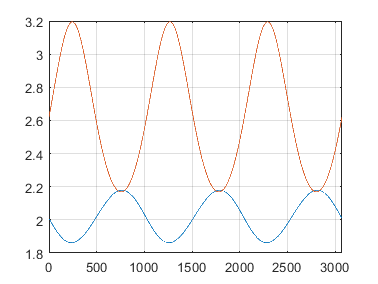

T_ron = PhaseOrder(ron, Fin(end), Fs);
T_ron_o = PhaseOrder(ron_o, Fin(end), Fs);
figure
plot(repmat(T_ron.Value,3,1));
hold on;
plot(repmat(T_ron_o.Value,3,1));
hold off;
grid on; box on

% sinad(ron,Fs)
[~, harmpower, harmfreq]= thd(repmat(ron_o,1,4),Fs, 5, 'aliased')

harmpower =    -8.8903
  -29.1979
  -49.5055
  -69.8131
  -90.1207


harmfreq = 1.0e+06 *

    4.8730
    0.2539
    4.6191
    0.5078
    4.3652


harmpower(2) - harmpower(1)

ans = -20.3076

harmpower(3) - harmpower(1)

ans = -40.6152


[~, harmpower, harmfreq]= thd(repmat(ron,1,4),Fs, 5, 'aliased')

harmpower =   -19.0300
  -49.5100
  -86.0000
 -304.0790
 -305.4060


harmfreq = 1.0e+06 *

    4.8730
    0.2539
    4.6191
    0.5078
    4.3654


harmpower(2) - harmpower(1)

ans = -30.4800

harmpower(3) - harmpower(1)

ans = -66.9700